**1 (i) Desiging Feedback Controller **

clear
close all
clc

% State space matrices
A = [-10 0 10;0 -100 100;0 0 -1];
B = [0; 0 ; 1];
C  = [0 0 1];
Dr=0;
sys = ss(A,B,C,0);

% LMI to design feedback controller which guarantees L2 gain < 2
epsilon = 10^-6;
gamma=2;
lambda = 10^-5;

cvx_begin sdp
cvx_solver SDPT3
cvx_precision high

n = length(A);
variable Y(n,n) symmetric;
variable Z(1,n) ;

 LMI1 = [[Y*A' + A*Y + 2*lambda*Y + Z'*B'+ B*Z + epsilon*eye(n) , B, Y*C']; 
 [ B' , -gamma*eye(1) , Dr'];
 [ C*Y , Dr , -gamma*eye(1)]] <= 0;


 LMI2 = [[Y*A' + A*Y + 2*lambda*Y + epsilon*eye(n) , B, Y*C']; 
 [ B' , -gamma*eye(1) , Dr'];
 [ C*Y , Dr , -gamma*eye(1)]] <= 0;
cvx_end

 
Calling SDPT3 4.0: 30 variables, 9 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  9
 dim. of sdp    var  = 10,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.6e+01|5.9e+01|7.7e+03| 7.999999e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.563|0.905|1.6e+01|5.6e+00|1.5e+03| 8.878698e+01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.810|0.988|3.0e+00|7.1e-02|3.6e+02| 1.317795e+02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.985|1.000|4.5e-02|5.8e-04|6.1e+00| 2.776812e+00  0.000000e+

% state feedback controller
K =Z*inv(Y)

K =     2.3616   31.6259  -38.3700


**1 (i) Simulating for Contraction Property**

% Checking contraction property using constant reference r=3 
T=5;
t=0:.01:T;
r0=3*ones(size(t));
r.time=t';
r.signals.values=r0';
x0=0;
samples=1000;
SIM1 = sim('coursework2model1', linspace(0,T,samples));

figure
plot(SIM1.state.data(:,1),'r','linewidth',1)
grid on
hold on
x0=1;
SIM2 = sim('coursework2model1', linspace(0,T,samples));

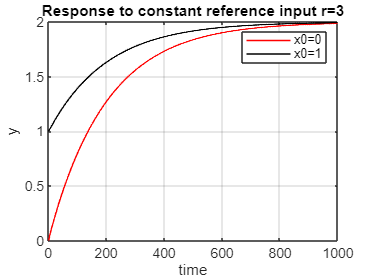

plot(SIM2.state.data(:,1),'k','linewidth',1)
ylabel('y')
xlabel('time')
title('Response to constant reference input r=3')
legend('x0=0','x0=1')


% checking contraction property using sinusoidal reference
T=5;
t=0:.01:T;
r0=3*sin(5*t);
r.time=t';
r.signals.values=r0';
x0=0;
samples=1000;
SIM3 = sim('coursework2model1', linspace(0,T,samples));

figure(2)
plot(SIM3.state.data(:,1),'r','linewidth',1)
hold on
x0=1;
SIM4 = sim('coursework2model1', linspace(0,T,samples));

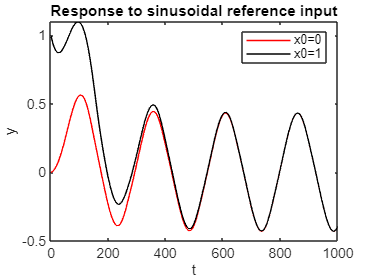

plot(SIM4.state.data(:,1),'k','linewidth',1)
ylabel('y')
xlabel('t')
title('Response to sinusoidal reference input')
legend('x0=0','x0=1')

**1 (i) Checking for L2 Incremental Gain **

% Checking if the L2 incremental gain satisfies using r1=3 and r2=10
% r1=3
r1=3*ones(size(t));
r.time=t';
r.signals.values=r1';
x0=0;
samples=501;
% output y1 
SIM5 = sim('coursework2model1', linspace(0,T,samples));

y1=SIM5.state.data(:,1)

y1 =          0
    0.0261
    0.0489
    0.0705
    0.0915
    0.1118
    0.1318
    0.1513
    0.1705
    0.1894


y1=y1'

y1 =          0    0.0261    0.0489    0.0705    0.0915    0.1118    0.1318    0.1513    0.1705    0.1894    0.2080    0.2263    0.2444    0.2622    0.2798    0.2971    0.3143    0.3313    0.3480    0.3646    0.3810    0.3972    0.4133    0.4292    0.4449    0.4604    0.4758    0.4910    0.5061    0.5210    0.5357    0.5503    0.5648    0.5791    0.5933    0.6073    0.6211    0.6349    0.6485    0.6619    0.6753    0.6885    0.7015    0.7144    0.7272    0.7399    0.7525    0.7649    0.7772    0.7894


% r2=10
r2=10*ones(size(t));
r.time=t';
r.signals.values=r2';
x0=0;
samples=501;
% output y2 
SIM6 = sim('coursework2model1', linspace(0,T,samples));

y2=SIM6.state.data(:,1)

y2 =          0
    0.0917
    0.1804
    0.2682
    0.3551
    0.4411
    0.5263
    0.6106
    0.6940
    0.7767


y2=y2'

y2 =          0    0.0917    0.1804    0.2682    0.3551    0.4411    0.5263    0.6106    0.6940    0.7767    0.8585    0.9395    1.0197    1.0991    1.1777    1.2556    1.3326    1.4089    1.4845    1.5592    1.6333    1.7066    1.7792    1.8510    1.9221    1.9926    2.0623    2.1313    2.1997    2.2673    2.3343    2.4006    2.4663    2.5313    2.5957    2.6594    2.7225    2.7850    2.8468    2.9080    2.9686    3.0287    3.0881    3.1469    3.2051    3.2628    3.3199    3.3764    3.4324    3.4878



% Calculating gamma
Q1 = trapz(t,(y2-y1))

Q1 = 28.0269

Q2 = trapz(t,(r2-r1))

Q2 = 35

gamma=sqrt(Q1)/sqrt(Q2)

gamma = 0.8949

**1 (iii) LMI gain design to enforce p dominance and instability at the equilibrum**

epsilon = 10^-6

epsilon = 1.0000e-06

lambda = 20

lambda = 20


cvx_begin sdp
    n = length(A);
    variable Y(n,n) symmetric
    variable Z(1,n)
 
    LMI1 = A*Y+Y*A'+2*lambda*Y+Z'*B'+B*Z+epsilon*eye(n)<= 0;

    LMI2 = A*Y+Y*A'+2*lambda*Y+epsilon*eye(n)<= 0;

    LMI3 = Y*A'+A*Y+Z'*B'+B*Z+epsilon*eye(n)<= 0;

cvx_end

 
Calling SDPT3 4.0: 18 variables, 9 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  9
 dim. of sdp    var  =  9,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.0e+02|2.3e+02|6.6e+03|-3.452632e-05  0.000000e+00| 0:0:00| chol  1  1 
 1|0.776|0.946|2.0e+02|1.2e+01|1.2e+03|-3.533380e-05  0.000000e+00| 0:0:00| chol  1  1 
 2|0.846|1.000|3.1e+01|1.0e-02|1.8e+02|-2.264099e-05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.988|1.000|3.8e-01|1.0e-03|2.2e+00|-2.810205e-07  0.000000e+



 % The state feedback controller is then :
K =Z*inv(Y)

K =  -404.3269   76.9645  243.3160



A_cl = A - B*K;
disp('Closed-loop eigenvalues:')

Closed-loop eigenvalues:


disp(eig(A_cl))

   1.0e+02 *

   0.0256 + 0.0000i
  -1.7844 + 0.2452i
  -1.7844 - 0.2452i



**1 (iii) Switching on/ off oscillations **

% Constant reference 
T=50;
t=0:.01:T;
% r0 = 0.5
r0=0.5*ones(size(t));
r.time=t';
r.signals.values=r0';
x0=0;
samples=1000;
SIM7 = sim('coursework2model1', linspace(0,T,samples))

SIM7 =   Simulink.SimulationOutput:

                  state: [1x1 timeseries] 
                   tout: [1000x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


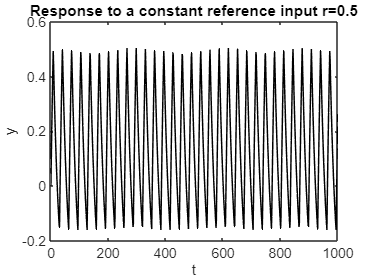

figure
plot(SIM7.state.data(:,1),'k','linewidth',1)
ylabel('y')
xlabel('t')
title('Response to a constant reference input r=0.5')



% r0 = 1
r0=1*ones(size(t));
r.time=t';
r.signals.values=r0';
x0=0;
samples=1000;
SIM8 = sim('coursework2model1', linspace(0,T,samples))

SIM8 =   Simulink.SimulationOutput:

                  state: [1x1 timeseries] 
                   tout: [1000x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


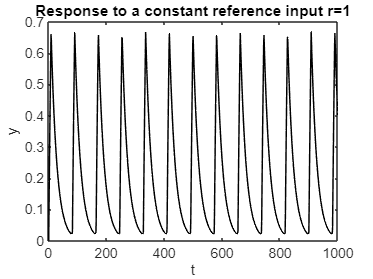

figure
plot(SIM8.state.data(:,1),'k','linewidth',1)
ylabel('y')
xlabel('t')
title('Response to a constant reference input r=1')


% r0 = 1.5 
r0=1.5*ones(size(t));
r.time=t';
r.signals.values=r0';
x0=0;
samples=1000;
SIM9 = sim('coursework2model1', linspace(0,T,samples))

SIM9 =   Simulink.SimulationOutput:

                  state: [1x1 timeseries] 
                   tout: [1000x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


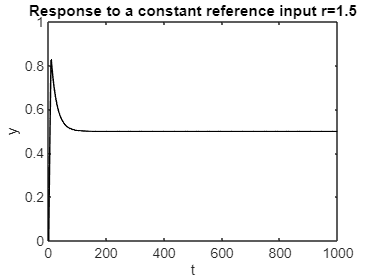

figure
plot(SIM9.state.data(:,1),'k','linewidth',1)
ylabel('y')
xlabel('t')
title('Response to a constant reference input r=1.5')

**1 (iii) R-2dom and R-inst**

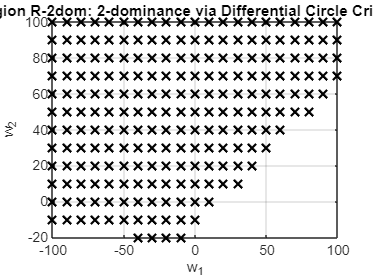

omega = logspace(-2, 2, 200);
w1_R2dom = [];
w2_R2dom = [];

% Sweep for R2dom 
for w1 = -100:10:100
    for w2 = -100:10:100
        C = [-w1, -w2, 0];
        A_shift = A + 20*eye(3);  % shift by lambda=20
        sys = ss(A_shift, B, C, 0);     
        H = squeeze(freqresp(sys, omega));  
        % Check if the entire Nyquist locus is to the right of -1
        if all(real(H) > -1)
            w1_R2dom = [w1_R2dom, w1];
            w2_R2dom = [w2_R2dom, w2];
        end
    end
end

% Plot R2dom
figure;
plot(w1_R2dom, w2_R2dom, 'kx', 'MarkerSize',8, 'LineWidth',1.5);
xlabel('w_1');
ylabel('w_2');
title('Region R-2dom: 2-dominance via Differential Circle Criterion');
grid on;


w1_Rinst = [];
w2_Rinst = [];

% Sweep for Rinst 
for i = 1:length(w1_R2dom)
    w1 = w1_R2dom(i);
    w2 = w2_R2dom(i);
    C = [-w1, -w2, 0];
    sys1 = ss(A, B, C, 0);   
    H1 = squeeze(freqresp(sys1, omega))
    ind = find(real(H1) < -1);
    if ~isempty(ind)
        phases = angle(H1(ind));
        % Check if any phase is nearly pi (or -pi)
        if any(abs(phases) > 0.95*pi)
            w1_Rinst = [w1_Rinst, w1];
            w2_Rinst = [w2_Rinst, w2];
        end
    end
end

H1 = 1.0e+02 *

   1.0999 - 0.0120i
   1.0999 - 0.0126i
   1.0999 - 0.0132i
   1.0998 - 0.0138i
   1.0998 - 0.0145i
   1.0998 - 0.0151i
   1.0998 - 0.0159i
   1.0998 - 0.0166i
   1.0997 - 0.0174i
   1.0997 - 0.0182i


H1 =   99.9889 - 1.0999i
  99.9878 - 1.1520i
  99.9866 - 1.2065i
  99.9853 - 1.2637i
  99.9839 - 1.3235i
  99.9824 - 1.3862i
  99.9807 - 1.4518i
  99.9788 - 1.5206i
  99.9767 - 1.5926i
  99.9745 - 1.6680i


H1 =   89.9899 - 0.9989i
  89.9889 - 1.0462i
  89.9879 - 1.0958i
  89.9867 - 1.1476i
  89.9854 - 1.2020i
  89.9840 - 1.2589i
  89.9824 - 1.3185i
  89.9807 - 1.3810i
  89.9788 - 1.4464i
  89.9768 - 1.5148i


H1 =   79.9909 - 0.8979i
  79.9900 - 0.9404i
  79.9891 - 0.9850i
  79.9880 - 1.0316i
  79.9869 - 1.0805i
  79.9856 - 1.1316i
  79.9842 - 1.1852i
  79.9826 - 1.2414i
  79.9810 - 1.3001i
  79.9791 - 1.3617i


H1 =   69.9919 - 0.7969i
  69.9911 - 0.8347i
  69.9903 - 0.8742i
  69.9893 - 0.9156i
  69.9883 - 0.9590i
  69.9872 - 1.0044i
  69.9859 - 1.0519i
  69.9846 - 1.1017i
  69.9831 - 1.1539i
  69.9814 - 1.2085i


H1 =   59.9929 - 0.6959i
  59.9923 - 0.7289i
  59.9915 - 0.7634i
  59.9907 - 0.7996i
  59.9898 - 0.8374i
  59.9888 - 0.8771i
  59.9877 - 0.9186i
  59.9865 - 0.9621i
  59.9852 - 1.0077i
  59.9838 - 1.0554i


H1 =   49.9940 - 0.5949i
  49.9934 - 0.6231i
  49.9927 - 0.6526i
  49.9920 - 0.6835i
  49.9912 - 0.7159i
  49.9904 - 0.7498i
  49.9895 - 0.7853i
  49.9884 - 0.8225i
  49.9873 - 0.8614i
  49.9861 - 0.9022i


H1 =   39.9950 - 0.4939i
  39.9945 - 0.5173i
  39.9939 - 0.5418i
  39.9933 - 0.5675i
  39.9927 - 0.5944i
  39.9920 - 0.6225i
  39.9912 - 0.6520i
  39.9904 - 0.6829i
  39.9894 - 0.7152i
  39.9884 - 0.7491i


H1 =   29.9960 - 0.3930i
  29.9956 - 0.4116i
  29.9952 - 0.4311i
  29.9947 - 0.4515i
  29.9942 - 0.4729i
  29.9936 - 0.4952i
  29.9930 - 0.5187i
  29.9923 - 0.5433i
  29.9916 - 0.5690i
  29.9907 - 0.5959i


H1 =   19.9970 - 0.2920i
  19.9967 - 0.3058i
  19.9964 - 0.3203i
  19.9960 - 0.3354i
  19.9956 - 0.3513i
  19.9952 - 0.3680i
  19.9947 - 0.3854i
  19.9942 - 0.4036i
  19.9937 - 0.4228i
  19.9931 - 0.4428i


H1 =    9.9980 - 0.1910i
   9.9978 - 0.2000i
   9.9976 - 0.2095i
   9.9973 - 0.2194i
   9.9971 - 0.2298i
   9.9968 - 0.2407i
   9.9965 - 0.2521i
   9.9962 - 0.2640i
   9.9958 - 0.2765i
   9.9954 - 0.2896i


H1 =   -0.0010 - 0.0900i
  -0.0011 - 0.0943i
  -0.0012 - 0.0987i
  -0.0013 - 0.1034i
  -0.0014 - 0.1083i
  -0.0016 - 0.1134i
  -0.0017 - 0.1188i
  -0.0019 - 0.1244i
  -0.0021 - 0.1303i
  -0.0023 - 0.1365i


H1 =   99.9890 - 1.0909i
  99.9879 - 1.1426i
  99.9868 - 1.1967i
  99.9855 - 1.2533i
  99.9841 - 1.3127i
  99.9825 - 1.3749i
  99.9808 - 1.4400i
  99.9790 - 1.5081i
  99.9769 - 1.5796i
  99.9747 - 1.6544i


H1 =   89.9900 - 0.9899i
  89.9890 - 1.0368i
  89.9880 - 1.0859i
  89.9868 - 1.1373i
  89.9855 - 1.1912i
  89.9841 - 1.2476i
  89.9826 - 1.3067i
  89.9809 - 1.3685i
  89.9791 - 1.4333i
  89.9770 - 1.5012i


H1 =   79.9910 - 0.8889i
  79.9902 - 0.9310i
  79.9892 - 0.9751i
  79.9881 - 1.0213i
  79.9870 - 1.0696i
  79.9857 - 1.1203i
  79.9844 - 1.1734i
  79.9828 - 1.2289i
  79.9812 - 1.2871i
  79.9793 - 1.3480i


H1 =   69.9920 - 0.7879i
  69.9913 - 0.8252i
  69.9904 - 0.8643i
  69.9895 - 0.9053i
  69.9885 - 0.9481i
  69.9873 - 0.9930i
  69.9861 - 1.0400i
  69.9848 - 1.0893i
  69.9833 - 1.1409i
  69.9817 - 1.1949i


H1 =   59.9930 - 0.6869i
  59.9924 - 0.7195i
  59.9916 - 0.7535i
  59.9908 - 0.7892i
  59.9899 - 0.8266i
  59.9889 - 0.8657i
  59.9879 - 0.9067i
  59.9867 - 0.9497i
  59.9854 - 0.9946i
  59.9840 - 1.0417i


H1 =   49.9941 - 0.5859i
  49.9935 - 0.6137i
  49.9928 - 0.6428i
  49.9921 - 0.6732i
  49.9914 - 0.7051i
  49.9906 - 0.7385i
  49.9896 - 0.7734i
  49.9886 - 0.8101i
  49.9875 - 0.8484i
  49.9863 - 0.8886i


H1 =   39.9951 - 0.4850i
  39.9946 - 0.5079i
  39.9941 - 0.5320i
  39.9935 - 0.5572i
  39.9928 - 0.5836i
  39.9922 - 0.6112i
  39.9914 - 0.6401i
  39.9906 - 0.6704i
  39.9896 - 0.7022i
  39.9886 - 0.7354i


H1 =   29.9961 - 0.3840i
  29.9957 - 0.4021i
  29.9953 - 0.4212i
  29.9948 - 0.4411i
  29.9943 - 0.4620i
  29.9938 - 0.4839i
  29.9932 - 0.5068i
  29.9925 - 0.5308i
  29.9918 - 0.5560i
  29.9910 - 0.5823i


H1 =   19.9971 - 0.2830i
  19.9968 - 0.2964i
  19.9965 - 0.3104i
  19.9961 - 0.3251i
  19.9958 - 0.3405i
  19.9954 - 0.3566i
  19.9949 - 0.3735i
  19.9944 - 0.3912i
  19.9939 - 0.4097i
  19.9933 - 0.4291i


H1 =    9.9981 - 0.1820i
   9.9979 - 0.1906i
   9.9977 - 0.1996i
   9.9975 - 0.2091i
   9.9972 - 0.2190i
   9.9970 - 0.2294i
   9.9967 - 0.2402i
   9.9964 - 0.2516i
   9.9960 - 0.2635i
   9.9956 - 0.2760i


H1 =   -0.0009 - 0.0810i
  -0.0010 - 0.0848i
  -0.0011 - 0.0888i
  -0.0012 - 0.0931i
  -0.0013 - 0.0975i
  -0.0014 - 0.1021i
  -0.0016 - 0.1069i
  -0.0017 - 0.1120i
  -0.0019 - 0.1173i
  -0.0021 - 0.1228i


H1 =   -9.9999 + 0.0200i
  -9.9999 + 0.0209i
  -9.9999 + 0.0219i
  -9.9999 + 0.0230i
  -9.9998 + 0.0241i
  -9.9998 + 0.0252i
  -9.9998 + 0.0264i
  -9.9998 + 0.0276i
  -9.9998 + 0.0290i
  -9.9997 + 0.0303i


H1 =   89.9901 - 0.9809i
  89.9892 - 1.0274i
  89.9881 - 1.0760i
  89.9869 - 1.1270i
  89.9857 - 1.1803i
  89.9843 - 1.2362i
  89.9828 - 1.2948i
  89.9811 - 1.3561i
  89.9793 - 1.4203i
  89.9773 - 1.4876i


H1 =   79.9911 - 0.8799i
  79.9903 - 0.9216i
  79.9893 - 0.9652i
  79.9883 - 1.0109i
  79.9871 - 1.0588i
  79.9859 - 1.1090i
  79.9845 - 1.1615i
  79.9830 - 1.2165i
  79.9814 - 1.2741i
  79.9796 - 1.3344i


H1 =   69.9921 - 0.7789i
  69.9914 - 0.8158i
  69.9905 - 0.8544i
  69.9896 - 0.8949i
  69.9886 - 0.9373i
  69.9875 - 0.9817i
  69.9863 - 1.0282i
  69.9850 - 1.0769i
  69.9835 - 1.1278i
  69.9819 - 1.1812i


H1 =   59.9931 - 0.6779i
  59.9925 - 0.7100i
  59.9917 - 0.7437i
  59.9909 - 0.7789i
  59.9901 - 0.8158i
  59.9891 - 0.8544i
  59.9880 - 0.8949i
  59.9869 - 0.9372i
  59.9856 - 0.9816i
  59.9842 - 1.0281i


H1 =   49.9942 - 0.5769i
  49.9936 - 0.6043i
  49.9930 - 0.6329i
  49.9923 - 0.6629i
  49.9915 - 0.6942i
  49.9907 - 0.7271i
  49.9898 - 0.7616i
  49.9888 - 0.7976i
  49.9877 - 0.8354i
  49.9865 - 0.8749i


H1 =   39.9952 - 0.4760i
  39.9947 - 0.4985i
  39.9942 - 0.5221i
  39.9936 - 0.5468i
  39.9930 - 0.5727i
  39.9923 - 0.5998i
  39.9916 - 0.6283i
  39.9908 - 0.6580i
  39.9899 - 0.6892i
  39.9889 - 0.7218i


H1 =   29.9962 - 0.3750i
  29.9958 - 0.3927i
  29.9954 - 0.4113i
  29.9949 - 0.4308i
  29.9945 - 0.4512i
  29.9939 - 0.4726i
  29.9933 - 0.4949i
  29.9927 - 0.5184i
  29.9920 - 0.5429i
  29.9912 - 0.5686i


H1 =   19.9972 - 0.2740i
  19.9969 - 0.2869i
  19.9966 - 0.3005i
  19.9963 - 0.3148i
  19.9959 - 0.3297i
  19.9955 - 0.3453i
  19.9951 - 0.3616i
  19.9946 - 0.3788i
  19.9941 - 0.3967i
  19.9935 - 0.4155i


H1 =    9.9982 - 0.1730i
   9.9980 - 0.1812i
   9.9978 - 0.1898i
   9.9976 - 0.1987i
   9.9974 - 0.2082i
   9.9971 - 0.2180i
   9.9968 - 0.2283i
   9.9965 - 0.2391i
   9.9962 - 0.2505i
   9.9958 - 0.2623i


H1 =   -0.0008 - 0.0720i
  -0.0009 - 0.0754i
  -0.0010 - 0.0790i
  -0.0011 - 0.0827i
  -0.0012 - 0.0866i
  -0.0013 - 0.0907i
  -0.0014 - 0.0950i
  -0.0015 - 0.0995i
  -0.0017 - 0.1042i
  -0.0018 - 0.1092i


H1 =   -9.9998 + 0.0290i
  -9.9998 + 0.0304i
  -9.9997 + 0.0318i
  -9.9997 + 0.0333i
  -9.9997 + 0.0349i
  -9.9997 + 0.0365i
  -9.9996 + 0.0383i
  -9.9996 + 0.0401i
  -9.9996 + 0.0420i
  -9.9995 + 0.0440i


H1 =  -19.9988 + 0.1300i
 -19.9987 + 0.1361i
 -19.9985 + 0.1426i
 -19.9984 + 0.1493i
 -19.9982 + 0.1564i
 -19.9981 + 0.1638i
 -19.9979 + 0.1716i
 -19.9977 + 0.1797i
 -19.9974 + 0.1882i
 -19.9972 + 0.1971i


H1 =   79.9912 - 0.8709i
  79.9904 - 0.9122i
  79.9894 - 0.9554i
  79.9884 - 1.0006i
  79.9873 - 1.0480i
  79.9861 - 1.0976i
  79.9847 - 1.1496i
  79.9832 - 1.2040i
  79.9816 - 1.2610i
  79.9798 - 1.3208i


H1 =   69.9922 - 0.7699i
  69.9915 - 0.8064i
  69.9907 - 0.8446i
  69.9897 - 0.8846i
  69.9887 - 0.9265i
  69.9877 - 0.9703i
  69.9865 - 1.0163i
  69.9851 - 1.0644i
  69.9837 - 1.1148i
  69.9821 - 1.1676i


H1 =   59.9932 - 0.6689i
  59.9926 - 0.7006i
  59.9919 - 0.7338i
  59.9911 - 0.7685i
  59.9902 - 0.8049i
  59.9893 - 0.8431i
  59.9882 - 0.8830i
  59.9871 - 0.9248i
  59.9858 - 0.9686i
  59.9845 - 1.0144i


H1 =   49.9943 - 0.5679i
  49.9937 - 0.5948i
  49.9931 - 0.6230i
  49.9924 - 0.6525i
  49.9917 - 0.6834i
  49.9909 - 0.7158i
  49.9900 - 0.7497i
  49.9890 - 0.7852i
  49.9879 - 0.8224i
  49.9868 - 0.8613i


H1 =   39.9953 - 0.4670i
  39.9948 - 0.4891i
  39.9943 - 0.5122i
  39.9937 - 0.5365i
  39.9931 - 0.5619i
  39.9925 - 0.5885i
  39.9917 - 0.6164i
  39.9909 - 0.6456i
  39.9901 - 0.6761i
  39.9891 - 0.7081i


H1 =   29.9963 - 0.3660i
  29.9959 - 0.3833i
  29.9955 - 0.4014i
  29.9951 - 0.4205i
  29.9946 - 0.4404i
  29.9941 - 0.4612i
  29.9935 - 0.4831i
  29.9929 - 0.5059i
  29.9922 - 0.5299i
  29.9914 - 0.5550i


H1 =   19.9973 - 0.2650i
  19.9970 - 0.2775i
  19.9967 - 0.2907i
  19.9964 - 0.3044i
  19.9961 - 0.3188i
  19.9957 - 0.3339i
  19.9953 - 0.3498i
  19.9948 - 0.3663i
  19.9943 - 0.3837i
  19.9937 - 0.4018i


H1 =    9.9983 - 0.1640i
   9.9981 - 0.1717i
   9.9979 - 0.1799i
   9.9977 - 0.1884i
   9.9975 - 0.1973i
   9.9973 - 0.2067i
   9.9970 - 0.2165i
   9.9967 - 0.2267i
   9.9964 - 0.2374i
   9.9961 - 0.2487i


H1 = 200×1
  -0.0007 - 0.0630i
  -0.0008 - 0.0660i
  -0.0008 - 0.0691i
  -0.0009 - 0.0724i
  -0.0010 - 0.0758i
  -0.0011 - 0.0794i
  -0.0012 - 0.0831i
  -0.0013 - 0.0871i
  -0.0015 - 0.0912i
  -0.0016 - 0.0955i


H1 = 200×1
  -9.9997 + 0.0380i
  -9.9997 + 0.0398i
  -9.9996 + 0.0417i
  -9.9996 + 0.0437i
  -9.9995 + 0.0457i
  -9.9995 + 0.0479i
  -9.9995 + 0.0502i
  -9.9994 + 0.0525i
  -9.9993 + 0.0550i
  -9.9993 + 0.0576i


H1 = 200×1
 -19.9987 + 0.1390i
 -19.9986 + 0.1456i
 -19.9984 + 0.1525i
 -19.9983 + 0.1597i
 -19.9981 + 0.1672i
 -19.9979 + 0.1752i
 -19.9977 + 0.1835i
 -19.9975 + 0.1921i
 -19.9972 + 0.2012i
 -19.9970 + 0.2108i


H1 = 200×1
 -29.9977 + 0.2400i
 -29.9974 + 0.2513i
 -29.9972 + 0.2632i
 -29.9969 + 0.2757i
 -29.9966 + 0.2888i
 -29.9963 + 0.3024i
 -29.9959 + 0.3168i
 -29.9955 + 0.3318i
 -29.9951 + 0.3475i
 -29.9946 + 0.3639i


H1 = 200×1
  69.9923 - 0.7609i
  69.9916 - 0.7970i
  69.9908 - 0.8347i
  69.9899 - 0.8742i
  69.9889 - 0.9156i
  69.9878 - 0.9590i
  69.9866 - 1.0044i
  69.9853 - 1.0520i
  69.9839 - 1.1018i
  69.9824 - 1.1540i


H1 = 200×1
  59.9933 - 0.6599i
  59.9927 - 0.6912i
  59.9920 - 0.7239i
  59.9912 - 0.7582i
  59.9904 - 0.7941i
  59.9894 - 0.8317i
  59.9884 - 0.8711i
  59.9873 - 0.9124i
  59.9860 - 0.9556i
  59.9847 - 1.0008i


H1 = 200×1
  49.9944 - 0.5589i
  49.9938 - 0.5854i
  49.9932 - 0.6131i
  49.9925 - 0.6422i
  49.9918 - 0.6726i
  49.9910 - 0.7044i
  49.9902 - 0.7378i
  49.9892 - 0.7727i
  49.9882 - 0.8093i
  49.9870 - 0.8476i


H1 = 200×1
  39.9954 - 0.4580i
  39.9949 - 0.4796i
  39.9944 - 0.5024i
  39.9939 - 0.5261i
  39.9933 - 0.5511i
  39.9926 - 0.5772i
  39.9919 - 0.6045i
  39.9911 - 0.6331i
  39.9903 - 0.6631i
  39.9893 - 0.6945i


H1 = 200×1
  29.9964 - 0.3570i
  29.9960 - 0.3739i
  29.9956 - 0.3916i
  29.9952 - 0.4101i
  29.9947 - 0.4295i
  29.9942 - 0.4499i
  29.9937 - 0.4712i
  29.9931 - 0.4935i
  29.9924 - 0.5169i
  29.9917 - 0.5413i


H1 = 200×1
  19.9974 - 0.2560i
  19.9971 - 0.2681i
  19.9968 - 0.2808i
  19.9965 - 0.2941i
  19.9962 - 0.3080i
  19.9958 - 0.3226i
  19.9954 - 0.3379i
  19.9950 - 0.3539i
  19.9945 - 0.3706i
  19.9940 - 0.3882i


H1 = 200×1
   9.9984 - 0.1550i
   9.9982 - 0.1623i
   9.9981 - 0.1700i
   9.9979 - 0.1781i
   9.9977 - 0.1865i
   9.9974 - 0.1953i
   9.9972 - 0.2046i
   9.9969 - 0.2143i
   9.9966 - 0.2244i
   9.9963 - 0.2350i


H1 = 200×1
  -0.0006 - 0.0540i
  -0.0007 - 0.0566i
  -0.0007 - 0.0592i
  -0.0008 - 0.0620i
  -0.0009 - 0.0650i
  -0.0010 - 0.0680i
  -0.0010 - 0.0713i
  -0.0011 - 0.0746i
  -0.0013 - 0.0782i
  -0.0014 - 0.0819i


H1 = 200×1
  -9.9996 + 0.0470i
  -9.9995 + 0.0492i
  -9.9995 + 0.0516i
  -9.9995 + 0.0540i
  -9.9994 + 0.0566i
  -9.9993 + 0.0592i
  -9.9993 + 0.0620i
  -9.9992 + 0.0650i
  -9.9991 + 0.0680i
  -9.9991 + 0.0713i


H1 = 200×1
 -19.9986 + 0.1480i
 -19.9984 + 0.1550i
 -19.9983 + 0.1623i
 -19.9981 + 0.1700i
 -19.9979 + 0.1781i
 -19.9977 + 0.1865i
 -19.9975 + 0.1953i
 -19.9973 + 0.2046i
 -19.9970 + 0.2143i
 -19.9967 + 0.2244i


H1 = 200×1
 -29.9976 + 0.2490i
 -29.9973 + 0.2608i
 -29.9971 + 0.2731i
 -29.9968 + 0.2861i
 -29.9965 + 0.2996i
 -29.9961 + 0.3138i
 -29.9958 + 0.3286i
 -29.9954 + 0.3442i
 -29.9949 + 0.3605i
 -29.9944 + 0.3776i


H1 = 200×1
 -39.9966 + 0.3500i
 -39.9962 + 0.3665i
 -39.9959 + 0.3839i
 -39.9955 + 0.4021i
 -39.9950 + 0.4211i
 -39.9945 + 0.4411i
 -39.9940 + 0.4620i
 -39.9934 + 0.4838i
 -39.9928 + 0.5067i
 -39.9921 + 0.5307i


H1 = 200×1
  59.9934 - 0.6509i
  59.9928 - 0.6818i
  59.9921 - 0.7141i
  59.9913 - 0.7479i
  59.9905 - 0.7833i
  59.9896 - 0.8204i
  59.9886 - 0.8592i
  59.9875 - 0.8999i
  59.9862 - 0.9425i
  59.9849 - 0.9872i


H1 = 200×1
  49.9945 - 0.5499i
  49.9939 - 0.5760i
  49.9933 - 0.6033i
  49.9927 - 0.6318i
  49.9920 - 0.6618i
  49.9912 - 0.6931i
  49.9903 - 0.7259i
  49.9894 - 0.7603i
  49.9884 - 0.7963i
  49.9872 - 0.8340i


H1 = 200×1
  39.9955 - 0.4490i
  39.9950 - 0.4702i
  39.9945 - 0.4925i
  39.9940 - 0.5158i
  39.9934 - 0.5402i
  39.9928 - 0.5658i
  39.9921 - 0.5926i
  39.9913 - 0.6207i
  39.9905 - 0.6501i
  39.9896 - 0.6808i


H1 = 200×1
  29.9965 - 0.3480i
  29.9961 - 0.3644i
  29.9958 - 0.3817i
  29.9953 - 0.3998i
  29.9949 - 0.4187i
  29.9944 - 0.4385i
  29.9938 - 0.4593i
  29.9933 - 0.4811i
  29.9926 - 0.5038i
  29.9919 - 0.5277i


H1 = 200×1
  19.9975 - 0.2470i
  19.9972 - 0.2587i
  19.9970 - 0.2709i
  19.9967 - 0.2838i
  19.9964 - 0.2972i
  19.9960 - 0.3113i
  19.9956 - 0.3260i
  19.9952 - 0.3414i
  19.9947 - 0.3576i
  19.9942 - 0.3745i


H1 = 200×1
   9.9985 - 0.1460i
   9.9983 - 0.1529i
   9.9982 - 0.1601i
   9.9980 - 0.1677i
   9.9978 - 0.1757i
   9.9976 - 0.1840i
   9.9974 - 0.1927i
   9.9971 - 0.2018i
   9.9968 - 0.2114i
   9.9965 - 0.2214i


H1 = 200×1
  -0.0005 - 0.0450i
  -0.0005 - 0.0471i
  -0.0006 - 0.0494i
  -0.0007 - 0.0517i
  -0.0007 - 0.0541i
  -0.0008 - 0.0567i
  -0.0009 - 0.0594i
  -0.0010 - 0.0622i
  -0.0010 - 0.0652i
  -0.0011 - 0.0682i


H1 = 200×1
  -9.9995 + 0.0560i
  -9.9994 + 0.0586i
  -9.9994 + 0.0614i
  -9.9993 + 0.0643i
  -9.9993 + 0.0674i
  -9.9992 + 0.0706i
  -9.9991 + 0.0739i
  -9.9990 + 0.0774i
  -9.9989 + 0.0811i
  -9.9988 + 0.0849i


H1 = 200×1
 -19.9985 + 0.1570i
 -19.9983 + 0.1644i
 -19.9982 + 0.1722i
 -19.9980 + 0.1804i
 -19.9978 + 0.1889i
 -19.9976 + 0.1978i
 -19.9974 + 0.2072i
 -19.9971 + 0.2170i
 -19.9968 + 0.2273i
 -19.9965 + 0.2381i


H1 = 200×1
 -29.9975 + 0.2580i
 -29.9972 + 0.2702i
 -29.9970 + 0.2830i
 -29.9967 + 0.2964i
 -29.9963 + 0.3104i
 -29.9960 + 0.3251i
 -29.9956 + 0.3405i
 -29.9952 + 0.3566i
 -29.9947 + 0.3735i
 -29.9942 + 0.3912i


H1 = 200×1
 -39.9965 + 0.3590i
 -39.9961 + 0.3760i
 -39.9957 + 0.3938i
 -39.9953 + 0.4124i
 -39.9949 + 0.4320i
 -39.9944 + 0.4524i
 -39.9938 + 0.4738i
 -39.9932 + 0.4963i
 -39.9926 + 0.5198i
 -39.9919 + 0.5444i


H1 = 200×1
 -49.9954 + 0.4600i
 -49.9950 + 0.4817i
 -49.9945 + 0.5046i
 -49.9940 + 0.5284i
 -49.9934 + 0.5535i
 -49.9928 + 0.5797i
 -49.9921 + 0.6071i
 -49.9913 + 0.6359i
 -49.9905 + 0.6660i
 -49.9895 + 0.6975i


H1 = 200×1
  59.9935 - 0.6419i
  59.9929 - 0.6723i
  59.9922 - 0.7042i
  59.9915 - 0.7375i
  59.9906 - 0.7725i
  59.9897 - 0.8090i
  59.9887 - 0.8473i
  59.9877 - 0.8875i
  59.9865 - 0.9295i
  59.9851 - 0.9735i


H1 = 200×1
  49.9946 - 0.5409i
  49.9940 - 0.5666i
  49.9934 - 0.5934i
  49.9928 - 0.6215i
  49.9921 - 0.6509i
  49.9913 - 0.6818i
  49.9905 - 0.7140i
  49.9896 - 0.7479i
  49.9886 - 0.7833i
  49.9875 - 0.8204i


H1 = 200×1
  39.9956 - 0.4400i
  39.9951 - 0.4608i
  39.9947 - 0.4826i
  39.9941 - 0.5055i
  39.9936 - 0.5294i
  39.9929 - 0.5545i
  39.9923 - 0.5807i
  39.9915 - 0.6082i
  39.9907 - 0.6370i
  39.9898 - 0.6672i


H1 = 200×1
  29.9966 - 0.3390i
  29.9962 - 0.3550i
  29.9959 - 0.3718i
  29.9955 - 0.3894i
  29.9950 - 0.4079i
  29.9946 - 0.4272i
  29.9940 - 0.4474i
  29.9934 - 0.4686i
  29.9928 - 0.4908i
  29.9921 - 0.5140i


H1 = 200×1
  19.9976 - 0.2380i
  19.9973 - 0.2492i
  19.9971 - 0.2611i
  19.9968 - 0.2734i
  19.9965 - 0.2864i
  19.9962 - 0.2999i
  19.9958 - 0.3141i
  19.9954 - 0.3290i
  19.9949 - 0.3446i
  19.9944 - 0.3609i


H1 = 200×1
   9.9986 - 0.1370i
   9.9985 - 0.1435i
   9.9983 - 0.1503i
   9.9981 - 0.1574i
   9.9980 - 0.1648i
   9.9978 - 0.1726i
   9.9975 - 0.1808i
   9.9973 - 0.1894i
   9.9970 - 0.1983i
   9.9968 - 0.2077i


H1 = 200×1
  -0.0004 - 0.0360i
  -0.0004 - 0.0377i
  -0.0005 - 0.0395i
  -0.0005 - 0.0414i
  -0.0006 - 0.0433i
  -0.0006 - 0.0454i
  -0.0007 - 0.0475i
  -0.0008 - 0.0498i
  -0.0008 - 0.0521i
  -0.0009 - 0.0546i


H1 = 200×1
  -9.9994 + 0.0650i
  -9.9993 + 0.0681i
  -9.9993 + 0.0713i
  -9.9992 + 0.0747i
  -9.9991 + 0.0782i
  -9.9990 + 0.0819i
  -9.9989 + 0.0858i
  -9.9988 + 0.0899i
  -9.9987 + 0.0941i
  -9.9986 + 0.0986i


H1 = 200×1
 -19.9984 + 0.1660i
 -19.9982 + 0.1738i
 -19.9981 + 0.1821i
 -19.9979 + 0.1907i
 -19.9977 + 0.1997i
 -19.9974 + 0.2092i
 -19.9972 + 0.2191i
 -19.9969 + 0.2295i
 -19.9966 + 0.2403i
 -19.9963 + 0.2517i


H1 = 200×1
 -29.9974 + 0.2670i
 -29.9971 + 0.2796i
 -29.9968 + 0.2929i
 -29.9965 + 0.3067i
 -29.9962 + 0.3213i
 -29.9958 + 0.3365i
 -29.9954 + 0.3524i
 -29.9950 + 0.3691i
 -29.9945 + 0.3866i
 -29.9939 + 0.4049i


H1 = 200×1
 -39.9964 + 0.3680i
 -39.9960 + 0.3854i
 -39.9956 + 0.4036i
 -39.9952 + 0.4228i
 -39.9947 + 0.4428i
 -39.9942 + 0.4637i
 -39.9937 + 0.4857i
 -39.9930 + 0.5087i
 -39.9924 + 0.5328i
 -39.9916 + 0.5580i


H1 = 200×1
 -49.9953 + 0.4690i
 -49.9949 + 0.4912i
 -49.9944 + 0.5144i
 -49.9939 + 0.5388i
 -49.9933 + 0.5643i
 -49.9926 + 0.5910i
 -49.9919 + 0.6190i
 -49.9911 + 0.6483i
 -49.9902 + 0.6790i
 -49.9893 + 0.7112i


H1 = 200×1
 -59.9943 + 0.5699i
 -59.9938 + 0.5969i
 -59.9932 + 0.6252i
 -59.9925 + 0.6548i
 -59.9918 + 0.6858i
 -59.9910 + 0.7183i
 -59.9901 + 0.7523i
 -59.9892 + 0.7879i
 -59.9881 + 0.8253i
 -59.9870 + 0.8643i


H1 = 200×1
  49.9947 - 0.5319i
  49.9941 - 0.5571i
  49.9936 - 0.5835i
  49.9929 - 0.6112i
  49.9923 - 0.6401i
  49.9915 - 0.6704i
  49.9907 - 0.7022i
  49.9898 - 0.7354i
  49.9888 - 0.7702i
  49.9877 - 0.8067i


H1 = 200×1
  39.9957 - 0.4310i
  39.9952 - 0.4514i
  39.9948 - 0.4727i
  39.9943 - 0.4951i
  39.9937 - 0.5186i
  39.9931 - 0.5431i
  39.9924 - 0.5689i
  39.9917 - 0.5958i
  39.9909 - 0.6240i
  39.9900 - 0.6536i


H1 = 200×1
  29.9967 - 0.3300i
  29.9963 - 0.3456i
  29.9960 - 0.3620i
  29.9956 - 0.3791i
  29.9952 - 0.3971i
  29.9947 - 0.4159i
  29.9942 - 0.4356i
  29.9936 - 0.4562i
  29.9930 - 0.4778i
  29.9923 - 0.5004i


H1 = 200×1
  19.9977 - 0.2290i
  19.9975 - 0.2398i
  19.9972 - 0.2512i
  19.9969 - 0.2631i
  19.9966 - 0.2755i
  19.9963 - 0.2886i
  19.9960 - 0.3022i
  19.9956 - 0.3166i
  19.9951 - 0.3315i
  19.9947 - 0.3472i


H1 = 200×1
   9.9987 - 0.1280i
   9.9986 - 0.1340i
   9.9984 - 0.1404i
   9.9983 - 0.1470i
   9.9981 - 0.1540i
   9.9979 - 0.1613i
   9.9977 - 0.1689i
   9.9975 - 0.1769i
   9.9973 - 0.1853i
   9.9970 - 0.1941i


H1 = 200×1
  -0.0003 - 0.0270i
  -0.0003 - 0.0283i
  -0.0004 - 0.0296i
  -0.0004 - 0.0310i
  -0.0004 - 0.0325i
  -0.0005 - 0.0340i
  -0.0005 - 0.0356i
  -0.0006 - 0.0373i
  -0.0006 - 0.0391i
  -0.0007 - 0.0409i


H1 = 200×1
  -9.9993 + 0.0740i
  -9.9992 + 0.0775i
  -9.9991 + 0.0812i
  -9.9991 + 0.0850i
  -9.9990 + 0.0890i
  -9.9989 + 0.0933i
  -9.9988 + 0.0977i
  -9.9986 + 0.1023i
  -9.9985 + 0.1071i
  -9.9984 + 0.1122i


H1 = 200×1
 -19.9983 + 0.1750i
 -19.9981 + 0.1833i
 -19.9979 + 0.1919i
 -19.9977 + 0.2010i
 -19.9975 + 0.2106i
 -19.9973 + 0.2205i
 -19.9970 + 0.2310i
 -19.9967 + 0.2419i
 -19.9964 + 0.2534i
 -19.9960 + 0.2654i


H1 = 200×1
 -29.9973 + 0.2760i
 -29.9970 + 0.2890i
 -29.9967 + 0.3027i
 -29.9964 + 0.3171i
 -29.9960 + 0.3321i
 -29.9957 + 0.3478i
 -29.9952 + 0.3643i
 -29.9948 + 0.3815i
 -29.9943 + 0.3996i
 -29.9937 + 0.4185i


H1 = 200×1
 -39.9963 + 0.3770i
 -39.9959 + 0.3948i
 -39.9955 + 0.4135i
 -39.9951 + 0.4331i
 -39.9946 + 0.4536i
 -39.9941 + 0.4751i
 -39.9935 + 0.4976i
 -39.9929 + 0.5211i
 -39.9922 + 0.5458i
 -39.9914 + 0.5717i


H1 = 200×1
 -49.9952 + 0.4780i
 -49.9948 + 0.5006i
 -49.9943 + 0.5243i
 -49.9937 + 0.5491i
 -49.9931 + 0.5751i
 -49.9925 + 0.6024i
 -49.9917 + 0.6309i
 -49.9909 + 0.6608i
 -49.9900 + 0.6921i
 -49.9891 + 0.7248i


H1 = 200×1
 -59.9942 + 0.5789i
 -59.9937 + 0.6064i
 -59.9931 + 0.6351i
 -59.9924 + 0.6652i
 -59.9917 + 0.6967i
 -59.9908 + 0.7296i
 -59.9900 + 0.7642i
 -59.9890 + 0.8004i
 -59.9879 + 0.8383i
 -59.9868 + 0.8780i


H1 = 200×1
 -69.9932 + 0.6799i
 -69.9926 + 0.7121i
 -69.9919 + 0.7459i
 -69.9911 + 0.7812i
 -69.9902 + 0.8182i
 -69.9892 + 0.8569i
 -69.9882 + 0.8975i
 -69.9871 + 0.9400i
 -69.9858 + 0.9845i
 -69.9844 + 1.0311i


H1 = 200×1
  39.9958 - 0.4220i
  39.9953 - 0.4419i
  39.9949 - 0.4629i
  39.9944 - 0.4848i
  39.9939 - 0.5078i
  39.9933 - 0.5318i
  39.9926 - 0.5570i
  39.9919 - 0.5834i
  39.9911 - 0.6110i
  39.9902 - 0.6399i


H1 = 200×1
  29.9968 - 0.3210i
  29.9965 - 0.3362i
  29.9961 - 0.3521i
  29.9957 - 0.3688i
  29.9953 - 0.3862i
  29.9949 - 0.4045i
  29.9944 - 0.4237i
  29.9938 - 0.4437i
  29.9932 - 0.4647i
  29.9926 - 0.4868i


H1 = 200×1
  19.9978 - 0.2200i
  19.9976 - 0.2304i
  19.9973 - 0.2413i
  19.9971 - 0.2527i
  19.9968 - 0.2647i
  19.9965 - 0.2772i
  19.9961 - 0.2904i
  19.9958 - 0.3041i
  19.9953 - 0.3185i
  19.9949 - 0.3336i


H1 = 200×1
   9.9988 - 0.1190i
   9.9987 - 0.1246i
   9.9985 - 0.1305i
   9.9984 - 0.1367i
   9.9982 - 0.1432i
   9.9981 - 0.1500i
   9.9979 - 0.1571i
   9.9977 - 0.1645i
   9.9975 - 0.1723i
   9.9972 - 0.1804i


H1 = 200×1
  -0.0002 - 0.0180i
  -0.0002 - 0.0189i
  -0.0002 - 0.0197i
  -0.0003 - 0.0207i
  -0.0003 - 0.0217i
  -0.0003 - 0.0227i
  -0.0003 - 0.0238i
  -0.0004 - 0.0249i
  -0.0004 - 0.0261i
  -0.0005 - 0.0273i


H1 = 200×1
  -9.9992 + 0.0830i
  -9.9991 + 0.0869i
  -9.9990 + 0.0910i
  -9.9989 + 0.0954i
  -9.9988 + 0.0999i
  -9.9987 + 0.1046i
  -9.9986 + 0.1095i
  -9.9985 + 0.1147i
  -9.9983 + 0.1202i
  -9.9981 + 0.1259i


H1 = 200×1
 -19.9982 + 0.1840i
 -19.9980 + 0.1927i
 -19.9978 + 0.2018i
 -19.9976 + 0.2114i
 -19.9974 + 0.2214i
 -19.9971 + 0.2319i
 -19.9968 + 0.2429i
 -19.9965 + 0.2544i
 -19.9962 + 0.2664i
 -19.9958 + 0.2790i


H1 = 200×1
 -29.9972 + 0.2850i
 -29.9969 + 0.2985i
 -29.9966 + 0.3126i
 -29.9963 + 0.3274i
 -29.9959 + 0.3429i
 -29.9955 + 0.3592i
 -29.9951 + 0.3762i
 -29.9946 + 0.3940i
 -29.9941 + 0.4126i
 -29.9935 + 0.4322i


H1 = 200×1
 -39.9962 + 0.3860i
 -39.9958 + 0.4042i
 -39.9954 + 0.4234i
 -39.9949 + 0.4434i
 -39.9944 + 0.4644i
 -39.9939 + 0.4864i
 -39.9933 + 0.5095i
 -39.9927 + 0.5336i
 -39.9919 + 0.5589i
 -39.9912 + 0.5853i


H1 = 200×1
 -49.9951 + 0.4870i
 -49.9947 + 0.5100i
 -49.9942 + 0.5342i
 -49.9936 + 0.5595i
 -49.9930 + 0.5860i
 -49.9923 + 0.6137i
 -49.9915 + 0.6428i
 -49.9907 + 0.6732i
 -49.9898 + 0.7051i
 -49.9888 + 0.7385i


H1 = 200×1
 -59.9941 + 0.5879i
 -59.9936 + 0.6158i
 -59.9929 + 0.6450i
 -59.9923 + 0.6755i
 -59.9915 + 0.7075i
 -59.9907 + 0.7410i
 -59.9898 + 0.7761i
 -59.9888 + 0.8128i
 -59.9877 + 0.8513i
 -59.9865 + 0.8916i


H1 = 200×1
 -69.9931 + 0.6889i
 -69.9925 + 0.7216i
 -69.9917 + 0.7557i
 -69.9909 + 0.7915i
 -69.9901 + 0.8290i
 -69.9891 + 0.8683i
 -69.9880 + 0.9094i
 -69.9869 + 0.9524i
 -69.9856 + 0.9975i
 -69.9842 + 1.0448i


H1 = 200×1
 -79.9921 + 0.7899i
 -79.9914 + 0.8273i
 -79.9905 + 0.8665i
 -79.9896 + 0.9076i
 -79.9886 + 0.9505i
 -79.9875 + 0.9955i
 -79.9863 + 1.0427i
 -79.9849 + 1.0921i
 -79.9835 + 1.1438i
 -79.9819 + 1.1979i


H1 = 200×1
  29.9969 - 0.3120i
  29.9966 - 0.3267i
  29.9962 - 0.3422i
  29.9959 - 0.3584i
  29.9955 - 0.3754i
  29.9950 - 0.3932i
  29.9945 - 0.4118i
  29.9940 - 0.4313i
  29.9934 - 0.4517i
  29.9928 - 0.4731i


H1 = 200×1
  19.9979 - 0.2110i
  19.9977 - 0.2210i
  19.9974 - 0.2314i
  19.9972 - 0.2424i
  19.9969 - 0.2539i
  19.9966 - 0.2659i
  19.9963 - 0.2785i
  19.9959 - 0.2917i
  19.9956 - 0.3055i
  19.9951 - 0.3200i


H1 = 200×1
   9.9989 - 0.1100i
   9.9988 - 0.1152i
   9.9987 - 0.1207i
   9.9985 - 0.1264i
   9.9984 - 0.1324i
   9.9982 - 0.1386i
   9.9981 - 0.1452i
   9.9979 - 0.1521i
   9.9977 - 0.1593i
   9.9974 - 0.1668i


H1 = 200×1
  -0.0001 - 0.0090i
  -0.0001 - 0.0094i
  -0.0001 - 0.0099i
  -0.0001 - 0.0103i
  -0.0001 - 0.0108i
  -0.0002 - 0.0113i
  -0.0002 - 0.0119i
  -0.0002 - 0.0124i
  -0.0002 - 0.0130i
  -0.0002 - 0.0136i


H1 = 200×1
  -9.9991 + 0.0920i
  -9.9990 + 0.0963i
  -9.9989 + 0.1009i
  -9.9988 + 0.1057i
  -9.9987 + 0.1107i
  -9.9986 + 0.1159i
  -9.9984 + 0.1214i
  -9.9983 + 0.1272i
  -9.9981 + 0.1332i
  -9.9979 + 0.1395i


H1 = 200×1
 -19.9981 + 0.1930i
 -19.9979 + 0.2021i
 -19.9977 + 0.2117i
 -19.9975 + 0.2217i
 -19.9972 + 0.2322i
 -19.9969 + 0.2432i
 -19.9967 + 0.2547i
 -19.9963 + 0.2668i
 -19.9960 + 0.2794i
 -19.9956 + 0.2927i


H1 = 200×1
 -29.9971 + 0.2940i
 -29.9968 + 0.3079i
 -29.9965 + 0.3225i
 -29.9961 + 0.3377i
 -29.9958 + 0.3537i
 -29.9953 + 0.3705i
 -29.9949 + 0.3880i
 -29.9944 + 0.4064i
 -29.9939 + 0.4257i
 -29.9933 + 0.4458i


H1 = 200×1
 -39.9961 + 0.3950i
 -39.9957 + 0.4137i
 -39.9953 + 0.4333i
 -39.9948 + 0.4538i
 -39.9943 + 0.4753i
 -39.9937 + 0.4978i
 -39.9931 + 0.5213i
 -39.9925 + 0.5460i
 -39.9917 + 0.5719i
 -39.9909 + 0.5990i


H1 = 200×1
 -49.9950 + 0.4960i
 -49.9946 + 0.5194i
 -49.9940 + 0.5440i
 -49.9935 + 0.5698i
 -49.9928 + 0.5968i
 -49.9921 + 0.6251i
 -49.9914 + 0.6547i
 -49.9905 + 0.6856i
 -49.9896 + 0.7181i
 -49.9886 + 0.7521i


H1 = 200×1
 -59.9940 + 0.5969i
 -59.9935 + 0.6252i
 -59.9928 + 0.6548i
 -59.9921 + 0.6858i
 -59.9914 + 0.7183i
 -59.9905 + 0.7523i
 -59.9896 + 0.7880i
 -59.9886 + 0.8253i
 -59.9875 + 0.8643i
 -59.9863 + 0.9053i


H1 = 200×1
 -69.9930 + 0.6979i
 -69.9924 + 0.7310i
 -69.9916 + 0.7656i
 -69.9908 + 0.8019i
 -69.9899 + 0.8398i
 -69.9889 + 0.8796i
 -69.9879 + 0.9213i
 -69.9867 + 0.9649i
 -69.9854 + 1.0106i
 -69.9840 + 1.0584i


H1 = 200×1
 -79.9920 + 0.7989i
 -79.9912 + 0.8368i
 -79.9904 + 0.8764i
 -79.9895 + 0.9179i
 -79.9884 + 0.9614i
 -79.9873 + 1.0069i
 -79.9861 + 1.0546i
 -79.9847 + 1.1045i
 -79.9833 + 1.1568i
 -79.9816 + 1.2116i


H1 = 200×1
 -89.9910 + 0.8999i
 -89.9901 + 0.9425i
 -89.9892 + 0.9872i
 -89.9881 + 1.0339i
 -89.9870 + 1.0829i
 -89.9857 + 1.1342i
 -89.9843 + 1.1879i
 -89.9828 + 1.2441i
 -89.9811 + 1.3030i
 -89.9793 + 1.3647i


H1 = 200×1
   9.9990 - 0.1010i
   9.9989 - 0.1058i
   9.9988 - 0.1108i
   9.9987 - 0.1160i
   9.9985 - 0.1215i
   9.9984 - 0.1273i
   9.9982 - 0.1333i
   9.9981 - 0.1396i
   9.9979 - 0.1462i
   9.9977 - 0.1532i


H1 = 200×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


H1 = 200×1
  -9.9990 + 0.1010i
  -9.9989 + 0.1058i
  -9.9988 + 0.1108i
  -9.9987 + 0.1160i
  -9.9985 + 0.1215i
  -9.9984 + 0.1273i
  -9.9982 + 0.1333i
  -9.9981 + 0.1396i
  -9.9979 + 0.1462i
  -9.9977 + 0.1532i


H1 = 200×1
 -19.9980 + 0.2020i
 -19.9978 + 0.2115i
 -19.9976 + 0.2216i
 -19.9973 + 0.2321i
 -19.9971 + 0.2430i
 -19.9968 + 0.2546i
 -19.9965 + 0.2666i
 -19.9961 + 0.2792i
 -19.9958 + 0.2925i
 -19.9954 + 0.3063i


H1 = 200×1
 -29.9970 + 0.3030i
 -29.9967 + 0.3173i
 -29.9964 + 0.3323i
 -29.9960 + 0.3481i
 -29.9956 + 0.3646i
 -29.9952 + 0.3818i
 -29.9947 + 0.3999i
 -29.9942 + 0.4189i
 -29.9936 + 0.4387i
 -29.9930 + 0.4595i


H1 = 200×1
 -39.9960 + 0.4040i
 -39.9956 + 0.4231i
 -39.9951 + 0.4431i
 -39.9947 + 0.4641i
 -39.9941 + 0.4861i
 -39.9936 + 0.5091i
 -39.9930 + 0.5332i
 -39.9923 + 0.5585i
 -39.9915 + 0.5849i
 -39.9907 + 0.6126i


H1 = 200×1
 -49.9950 + 0.5049i
 -49.9945 + 0.5289i
 -49.9939 + 0.5539i
 -49.9933 + 0.5801i
 -49.9927 + 0.6076i
 -49.9920 + 0.6364i
 -49.9912 + 0.6665i
 -49.9903 + 0.6981i
 -49.9894 + 0.7311i
 -49.9884 + 0.7658i


H1 = 200×1
 -59.9939 + 0.6059i
 -59.9934 + 0.6346i
 -59.9927 + 0.6647i
 -59.9920 + 0.6962i
 -59.9912 + 0.7291i
 -59.9904 + 0.7637i
 -59.9894 + 0.7998i
 -59.9884 + 0.8377i
 -59.9873 + 0.8774i
 -59.9861 + 0.9189i


H1 = 200×1
 -69.9929 + 0.7069i
 -69.9922 + 0.7404i
 -69.9915 + 0.7755i
 -69.9907 + 0.8122i
 -69.9898 + 0.8507i
 -69.9888 + 0.8909i
 -69.9877 + 0.9331i
 -69.9865 + 0.9773i
 -69.9852 + 1.0236i
 -69.9837 + 1.0721i


H1 = 200×1
 -79.9919 + 0.8079i
 -79.9911 + 0.8462i
 -79.9903 + 0.8863i
 -79.9893 + 0.9282i
 -79.9883 + 0.9722i
 -79.9872 + 1.0182i
 -79.9859 + 1.0664i
 -79.9846 + 1.1169i
 -79.9831 + 1.1698i
 -79.9814 + 1.2252i


H1 = 200×1
 -89.9909 + 0.9089i
 -89.9900 + 0.9520i
 -89.9891 + 0.9970i
 -89.9880 + 1.0443i
 -89.9868 + 1.0937i
 -89.9856 + 1.1455i
 -89.9842 + 1.1998i
 -89.9826 + 1.2566i
 -89.9809 + 1.3161i
 -89.9791 + 1.3784i


H1 = 200×1
 -99.9899 + 1.0099i
 -99.9889 + 1.0577i
 -99.9878 + 1.1078i
 -99.9867 + 1.1603i
 -99.9854 + 1.2152i
 -99.9840 + 1.2728i
 -99.9824 + 1.3331i
 -99.9807 + 1.3962i
 -99.9788 + 1.4623i
 -99.9768 + 1.5315i


H1 = 200×1
  -9.9989 + 0.1100i
  -9.9988 + 0.1152i
  -9.9987 + 0.1207i
  -9.9985 + 0.1264i
  -9.9984 + 0.1324i
  -9.9982 + 0.1386i
  -9.9981 + 0.1452i
  -9.9979 + 0.1521i
  -9.9977 + 0.1593i
  -9.9974 + 0.1668i


H1 = 200×1
 -19.9979 + 0.2110i
 -19.9977 + 0.2210i
 -19.9974 + 0.2314i
 -19.9972 + 0.2424i
 -19.9969 + 0.2539i
 -19.9966 + 0.2659i
 -19.9963 + 0.2785i
 -19.9959 + 0.2917i
 -19.9956 + 0.3055i
 -19.9951 + 0.3200i


H1 = 200×1
 -29.9969 + 0.3120i
 -29.9966 + 0.3267i
 -29.9962 + 0.3422i
 -29.9959 + 0.3584i
 -29.9955 + 0.3754i
 -29.9950 + 0.3932i
 -29.9945 + 0.4118i
 -29.9940 + 0.4313i
 -29.9934 + 0.4517i
 -29.9928 + 0.4731i


H1 = 200×1
 -39.9959 + 0.4130i
 -39.9955 + 0.4325i
 -39.9950 + 0.4530i
 -39.9945 + 0.4745i
 -39.9940 + 0.4969i
 -39.9934 + 0.5205i
 -39.9928 + 0.5451i
 -39.9921 + 0.5709i
 -39.9913 + 0.5979i
 -39.9905 + 0.6263i


H1 = 200×1
 -49.9949 + 0.5139i
 -49.9944 + 0.5383i
 -49.9938 + 0.5638i
 -49.9932 + 0.5905i
 -49.9925 + 0.6184i
 -49.9918 + 0.6477i
 -49.9910 + 0.6784i
 -49.9902 + 0.7105i
 -49.9892 + 0.7442i
 -49.9882 + 0.7794i


H1 = 200×1
 -59.9938 + 0.6149i
 -59.9932 + 0.6441i
 -59.9926 + 0.6746i
 -59.9919 + 0.7065i
 -59.9911 + 0.7400i
 -59.9902 + 0.7750i
 -59.9893 + 0.8117i
 -59.9882 + 0.8501i
 -59.9871 + 0.8904i
 -59.9858 + 0.9326i


H1 = 200×1
 -69.9928 + 0.7159i
 -69.9921 + 0.7498i
 -69.9914 + 0.7853i
 -69.9905 + 0.8225i
 -69.9896 + 0.8615i
 -69.9886 + 0.9023i
 -69.9875 + 0.9450i
 -69.9863 + 0.9898i
 -69.9850 + 1.0366i
 -69.9835 + 1.0857i


H1 = 200×1
 -79.9918 + 0.8169i
 -79.9910 + 0.8556i
 -79.9902 + 0.8961i
 -79.9892 + 0.9386i
 -79.9882 + 0.9830i
 -79.9870 + 1.0296i
 -79.9857 + 1.0783i
 -79.9844 + 1.1294i
 -79.9828 + 1.1829i
 -79.9812 + 1.2389i


H1 = 200×1
 -89.9908 + 0.9179i
 -89.9899 + 0.9614i
 -89.9889 + 1.0069i
 -89.9879 + 1.0546i
 -89.9867 + 1.1045i
 -89.9854 + 1.1568i
 -89.9840 + 1.2116i
 -89.9824 + 1.2690i
 -89.9807 + 1.3291i
 -89.9789 + 1.3920i


H1 = 200×1
 -99.9898 + 1.0189i
 -99.9888 + 1.0672i
 -99.9877 + 1.1177i
 -99.9865 + 1.1706i
 -99.9852 + 1.2261i
 -99.9838 + 1.2841i
 -99.9822 + 1.3449i
 -99.9805 + 1.4086i
 -99.9786 + 1.4753i
 -99.9765 + 1.5452i


H1 = 200×1
1.0e+02 *

  -1.0999 + 0.0112i
  -1.0999 + 0.0117i
  -1.0999 + 0.0123i
  -1.0999 + 0.0129i
  -1.0998 + 0.0135i
  -1.0998 + 0.0141i
  -1.0998 + 0.0148i
  -1.0998 + 0.0155i
  -1.0998 + 0.0162i
  -1.0997 + 0.0170i


H1 = 200×1
 -29.9968 + 0.3210i
 -29.9965 + 0.3362i
 -29.9961 + 0.3521i
 -29.9957 + 0.3688i
 -29.9953 + 0.3862i
 -29.9949 + 0.4045i
 -29.9944 + 0.4237i
 -29.9938 + 0.4437i
 -29.9932 + 0.4647i
 -29.9926 + 0.4868i


H1 = 200×1
 -39.9958 + 0.4220i
 -39.9953 + 0.4419i
 -39.9949 + 0.4629i
 -39.9944 + 0.4848i
 -39.9939 + 0.5078i
 -39.9933 + 0.5318i
 -39.9926 + 0.5570i
 -39.9919 + 0.5834i
 -39.9911 + 0.6110i
 -39.9902 + 0.6399i


H1 = 200×1
 -49.9948 + 0.5229i
 -49.9942 + 0.5477i
 -49.9937 + 0.5737i
 -49.9931 + 0.6008i
 -49.9924 + 0.6293i
 -49.9917 + 0.6591i
 -49.9909 + 0.6903i
 -49.9900 + 0.7230i
 -49.9890 + 0.7572i
 -49.9879 + 0.7931i


H1 = 200×1
 -59.9937 + 0.6239i
 -59.9931 + 0.6535i
 -59.9925 + 0.6844i
 -59.9917 + 0.7169i
 -59.9909 + 0.7508i
 -59.9901 + 0.7864i
 -59.9891 + 0.8236i
 -59.9880 + 0.8626i
 -59.9869 + 0.9034i
 -59.9856 + 0.9462i


H1 = 200×1
 -69.9927 + 0.7249i
 -69.9920 + 0.7593i
 -69.9913 + 0.7952i
 -69.9904 + 0.8329i
 -69.9895 + 0.8723i
 -69.9885 + 0.9136i
 -69.9873 + 0.9569i
 -69.9861 + 1.0022i
 -69.9848 + 1.0497i
 -69.9833 + 1.0994i


H1 = 200×1
 -79.9917 + 0.8259i
 -79.9909 + 0.8650i
 -79.9900 + 0.9060i
 -79.9891 + 0.9489i
 -79.9880 + 0.9938i
 -79.9868 + 1.0409i
 -79.9856 + 1.0902i
 -79.9842 + 1.1418i
 -79.9826 + 1.1959i
 -79.9810 + 1.2525i


H1 = 200×1
 -89.9907 + 0.9269i
 -89.9898 + 0.9708i
 -89.9888 + 1.0168i
 -89.9877 + 1.0649i
 -89.9865 + 1.1154i
 -89.9852 + 1.1682i
 -89.9838 + 1.2235i
 -89.9822 + 1.2814i
 -89.9805 + 1.3421i
 -89.9786 + 1.4057i


H1 = 200×1
 -99.9897 + 1.0279i
 -99.9887 + 1.0766i
 -99.9876 + 1.1276i
 -99.9864 + 1.1810i
 -99.9851 + 1.2369i
 -99.9836 + 1.2955i
 -99.9821 + 1.3568i
 -99.9803 + 1.4211i
 -99.9784 + 1.4884i
 -99.9763 + 1.5588i


H1 = 200×1
1.0e+02 *

  -1.0999 + 0.0113i
  -1.0999 + 0.0118i
  -1.0999 + 0.0124i
  -1.0999 + 0.0130i
  -1.0998 + 0.0136i
  -1.0998 + 0.0142i
  -1.0998 + 0.0149i
  -1.0998 + 0.0156i
  -1.0998 + 0.0163i
  -1.0997 + 0.0171i


H1 = 200×1
1.0e+02 *

  -1.1999 + 0.0123i
  -1.1999 + 0.0129i
  -1.1999 + 0.0135i
  -1.1998 + 0.0141i
  -1.1998 + 0.0148i
  -1.1998 + 0.0155i
  -1.1998 + 0.0162i
  -1.1998 + 0.0170i
  -1.1997 + 0.0178i
  -1.1997 + 0.0187i


H1 = 200×1
 -39.9957 + 0.4310i
 -39.9952 + 0.4514i
 -39.9948 + 0.4727i
 -39.9943 + 0.4951i
 -39.9937 + 0.5186i
 -39.9931 + 0.5431i
 -39.9924 + 0.5689i
 -39.9917 + 0.5958i
 -39.9909 + 0.6240i
 -39.9900 + 0.6536i


H1 = 200×1
 -49.9947 + 0.5319i
 -49.9941 + 0.5571i
 -49.9936 + 0.5835i
 -49.9929 + 0.6112i
 -49.9923 + 0.6401i
 -49.9915 + 0.6704i
 -49.9907 + 0.7022i
 -49.9898 + 0.7354i
 -49.9888 + 0.7702i
 -49.9877 + 0.8067i


H1 = 200×1
 -59.9936 + 0.6329i
 -59.9930 + 0.6629i
 -59.9923 + 0.6943i
 -59.9916 + 0.7272i
 -59.9908 + 0.7616i
 -59.9899 + 0.7977i
 -59.9889 + 0.8355i
 -59.9878 + 0.8750i
 -59.9867 + 0.9165i
 -59.9854 + 0.9599i


H1 = 200×1
 -69.9926 + 0.7339i
 -69.9919 + 0.7687i
 -69.9911 + 0.8051i
 -69.9903 + 0.8432i
 -69.9893 + 0.8832i
 -69.9883 + 0.9250i
 -69.9872 + 0.9688i
 -69.9859 + 1.0146i
 -69.9845 + 1.0627i
 -69.9830 + 1.1130i


H1 = 200×1
 -79.9916 + 0.8349i
 -79.9908 + 0.8745i
 -79.9899 + 0.9159i
 -79.9889 + 0.9592i
 -79.9879 + 1.0047i
 -79.9867 + 1.0523i
 -79.9854 + 1.1021i
 -79.9840 + 1.1543i
 -79.9824 + 1.2089i
 -79.9807 + 1.2662i


H1 = 200×1
 -89.9906 + 0.9359i
 -89.9897 + 0.9802i
 -89.9887 + 1.0267i
 -89.9876 + 1.0753i
 -89.9864 + 1.1262i
 -89.9851 + 1.1795i
 -89.9836 + 1.2354i
 -89.9821 + 1.2939i
 -89.9803 + 1.3552i
 -89.9784 + 1.4193i


H1 = 200×1
 -99.9896 + 1.0369i
 -99.9886 + 1.0860i
 -99.9875 + 1.1374i
 -99.9863 + 1.1913i
 -99.9849 + 1.2477i
 -99.9835 + 1.3068i
 -99.9819 + 1.3687i
 -99.9801 + 1.4335i
 -99.9782 + 1.5014i
 -99.9761 + 1.5725i


H1 = 200×1
1.0e+02 *

  -1.0999 + 0.0114i
  -1.0999 + 0.0119i
  -1.0999 + 0.0125i
  -1.0998 + 0.0131i
  -1.0998 + 0.0137i
  -1.0998 + 0.0143i
  -1.0998 + 0.0150i
  -1.0998 + 0.0157i
  -1.0998 + 0.0165i
  -1.0997 + 0.0173i


H1 = 200×1
1.0e+02 *

  -1.1999 + 0.0124i
  -1.1999 + 0.0130i
  -1.1999 + 0.0136i
  -1.1998 + 0.0142i
  -1.1998 + 0.0149i
  -1.1998 + 0.0156i
  -1.1998 + 0.0164i
  -1.1998 + 0.0171i
  -1.1997 + 0.0179i
  -1.1997 + 0.0188i


H1 = 200×1
1.0e+02 *

  -1.2999 + 0.0134i
  -1.2999 + 0.0140i
  -1.2998 + 0.0147i
  -1.2998 + 0.0154i
  -1.2998 + 0.0161i
  -1.2998 + 0.0169i
  -1.2998 + 0.0177i
  -1.2997 + 0.0185i
  -1.2997 + 0.0194i
  -1.2997 + 0.0203i


H1 = 200×1
 -59.9935 + 0.6419i
 -59.9929 + 0.6723i
 -59.9922 + 0.7042i
 -59.9915 + 0.7375i
 -59.9906 + 0.7725i
 -59.9897 + 0.8090i
 -59.9887 + 0.8473i
 -59.9877 + 0.8875i
 -59.9865 + 0.9295i
 -59.9851 + 0.9735i


H1 = 200×1
 -69.9925 + 0.7429i
 -69.9918 + 0.7781i
 -69.9910 + 0.8150i
 -69.9901 + 0.8536i
 -69.9892 + 0.8940i
 -69.9881 + 0.9363i
 -69.9870 + 0.9807i
 -69.9857 + 1.0271i
 -69.9843 + 1.0757i
 -69.9828 + 1.1267i


H1 = 200×1
 -79.9915 + 0.8439i
 -79.9907 + 0.8839i
 -79.9898 + 0.9257i
 -79.9888 + 0.9696i
 -79.9877 + 1.0155i
 -79.9865 + 1.0636i
 -79.9852 + 1.1140i
 -79.9838 + 1.1667i
 -79.9822 + 1.2220i
 -79.9805 + 1.2798i


H1 = 200×1
 -89.9905 + 0.9449i
 -89.9896 + 0.9897i
 -89.9886 + 1.0365i
 -89.9875 + 1.0856i
 -89.9863 + 1.1370i
 -89.9849 + 1.1909i
 -89.9835 + 1.2473i
 -89.9819 + 1.3063i
 -89.9801 + 1.3682i
 -89.9782 + 1.4330i


H1 = 200×1
 -99.9895 + 1.0459i
 -99.9885 + 1.0954i
 -99.9874 + 1.1473i
 -99.9861 + 1.2016i
 -99.9848 + 1.2586i
 -99.9833 + 1.3182i
 -99.9817 + 1.3806i
 -99.9799 + 1.4459i
 -99.9780 + 1.5144i
 -99.9758 + 1.5861i


H1 = 200×1
1.0e+02 *

  -1.0999 + 0.0115i
  -1.0999 + 0.0120i
  -1.0999 + 0.0126i
  -1.0998 + 0.0132i
  -1.0998 + 0.0138i
  -1.0998 + 0.0145i
  -1.0998 + 0.0151i
  -1.0998 + 0.0159i
  -1.0998 + 0.0166i
  -1.0997 + 0.0174i


H1 = 200×1
1.0e+02 *

  -1.1999 + 0.0125i
  -1.1999 + 0.0131i
  -1.1998 + 0.0137i
  -1.1998 + 0.0143i
  -1.1998 + 0.0150i
  -1.1998 + 0.0157i
  -1.1998 + 0.0165i
  -1.1998 + 0.0173i
  -1.1997 + 0.0181i
  -1.1997 + 0.0189i


H1 = 200×1
1.0e+02 *

  -1.2999 + 0.0135i
  -1.2999 + 0.0141i
  -1.2998 + 0.0148i
  -1.2998 + 0.0155i
  -1.2998 + 0.0162i
  -1.2998 + 0.0170i
  -1.2998 + 0.0178i
  -1.2997 + 0.0186i
  -1.2997 + 0.0195i
  -1.2997 + 0.0205i


H1 = 200×1
1.0e+02 *

  -1.3999 + 0.0145i
  -1.3998 + 0.0152i
  -1.3998 + 0.0159i
  -1.3998 + 0.0167i
  -1.3998 + 0.0174i
  -1.3998 + 0.0183i
  -1.3997 + 0.0191i
  -1.3997 + 0.0200i
  -1.3997 + 0.0210i
  -1.3997 + 0.0220i


H1 = 200×1
 -79.9914 + 0.8529i
 -79.9906 + 0.8933i
 -79.9897 + 0.9356i
 -79.9887 + 0.9799i
 -79.9876 + 1.0263i
 -79.9864 + 1.0749i
 -79.9851 + 1.1258i
 -79.9836 + 1.1791i
 -79.9820 + 1.2350i
 -79.9803 + 1.2935i


H1 = 200×1
 -89.9904 + 0.9539i
 -89.9895 + 0.9991i
 -89.9885 + 1.0464i
 -89.9873 + 1.0960i
 -89.9861 + 1.1479i
 -89.9848 + 1.2022i
 -89.9833 + 1.2591i
 -89.9817 + 1.3188i
 -89.9799 + 1.3812i
 -89.9779 + 1.4466i


H1 = 200×1
 -99.9894 + 1.0549i
 -99.9884 + 1.1049i
 -99.9872 + 1.1572i
 -99.9860 + 1.2120i
 -99.9847 + 1.2694i
 -99.9832 + 1.3295i
 -99.9815 + 1.3924i
 -99.9797 + 1.4584i
 -99.9778 + 1.5274i
 -99.9756 + 1.5998i


H1 = 200×1
1.0e+02 *

  -1.0999 + 0.0116i
  -1.0999 + 0.0121i
  -1.0999 + 0.0127i
  -1.0998 + 0.0133i
  -1.0998 + 0.0139i
  -1.0998 + 0.0146i
  -1.0998 + 0.0153i
  -1.0998 + 0.0160i
  -1.0998 + 0.0167i
  -1.0997 + 0.0175i


H1 = 200×1
1.0e+02 *

  -1.1999 + 0.0126i
  -1.1999 + 0.0132i
  -1.1998 + 0.0138i
  -1.1998 + 0.0144i
  -1.1998 + 0.0151i
  -1.1998 + 0.0158i
  -1.1998 + 0.0166i
  -1.1998 + 0.0174i
  -1.1997 + 0.0182i
  -1.1997 + 0.0191i


H1 = 200×1
1.0e+02 *

  -1.2999 + 0.0136i
  -1.2999 + 0.0142i
  -1.2998 + 0.0149i
  -1.2998 + 0.0156i
  -1.2998 + 0.0163i
  -1.2998 + 0.0171i
  -1.2998 + 0.0179i
  -1.2997 + 0.0188i
  -1.2997 + 0.0197i
  -1.2997 + 0.0206i


H1 = 200×1
1.0e+02 *

  -1.3999 + 0.0146i
  -1.3998 + 0.0153i
  -1.3998 + 0.0160i
  -1.3998 + 0.0168i
  -1.3998 + 0.0176i
  -1.3998 + 0.0184i
  -1.3997 + 0.0193i
  -1.3997 + 0.0202i
  -1.3997 + 0.0211i
  -1.3997 + 0.0221i


H1 = 200×1
1.0e+02 *

  -1.4998 + 0.0156i
  -1.4998 + 0.0163i
  -1.4998 + 0.0171i
  -1.4998 + 0.0179i
  -1.4998 + 0.0188i
  -1.4998 + 0.0197i
  -1.4997 + 0.0206i
  -1.4997 + 0.0216i
  -1.4997 + 0.0226i
  -1.4996 + 0.0237i


H1 = 200×1
 -99.9893 + 1.0639i
 -99.9883 + 1.1143i
 -99.9871 + 1.1671i
 -99.9859 + 1.2223i
 -99.9845 + 1.2802i
 -99.9830 + 1.3408i
 -99.9814 + 1.4043i
 -99.9795 + 1.4708i
 -99.9776 + 1.5405i
 -99.9754 + 1.6134i


H1 = 200×1
1.0e+02 *

  -1.0999 + 0.0116i
  -1.0999 + 0.0122i
  -1.0999 + 0.0128i
  -1.0998 + 0.0134i
  -1.0998 + 0.0140i
  -1.0998 + 0.0147i
  -1.0998 + 0.0154i
  -1.0998 + 0.0161i
  -1.0998 + 0.0169i
  -1.0997 + 0.0177i


H1 = 200×1
1.0e+02 *

  -1.1999 + 0.0127i
  -1.1999 + 0.0133i
  -1.1998 + 0.0139i
  -1.1998 + 0.0145i
  -1.1998 + 0.0152i
  -1.1998 + 0.0160i
  -1.1998 + 0.0167i
  -1.1998 + 0.0175i
  -1.1997 + 0.0183i
  -1.1997 + 0.0192i


H1 = 200×1
1.0e+02 *

  -1.2999 + 0.0137i
  -1.2998 + 0.0143i
  -1.2998 + 0.0150i
  -1.2998 + 0.0157i
  -1.2998 + 0.0164i
  -1.2998 + 0.0172i
  -1.2998 + 0.0180i
  -1.2997 + 0.0189i
  -1.2997 + 0.0198i
  -1.2997 + 0.0207i


H1 = 200×1
1.0e+02 *

  -1.3999 + 0.0147i
  -1.3998 + 0.0154i
  -1.3998 + 0.0161i
  -1.3998 + 0.0169i
  -1.3998 + 0.0177i
  -1.3998 + 0.0185i
  -1.3997 + 0.0194i
  -1.3997 + 0.0203i
  -1.3997 + 0.0213i
  -1.3997 + 0.0223i


H1 = 200×1
1.0e+02 *

  -1.4998 + 0.0157i
  -1.4998 + 0.0164i
  -1.4998 + 0.0172i
  -1.4998 + 0.0180i
  -1.4998 + 0.0189i
  -1.4997 + 0.0198i
  -1.4997 + 0.0207i
  -1.4997 + 0.0217i
  -1.4997 + 0.0227i
  -1.4996 + 0.0238i


H1 = 200×1
1.0e+02 *

  -1.5998 + 0.0167i
  -1.5998 + 0.0175i
  -1.5998 + 0.0183i
  -1.5998 + 0.0192i
  -1.5998 + 0.0201i
  -1.5997 + 0.0210i
  -1.5997 + 0.0220i
  -1.5997 + 0.0231i
  -1.5996 + 0.0242i
  -1.5996 + 0.0253i


H1 = 200×1
1.0e+02 *

  -1.1999 + 0.0127i
  -1.1999 + 0.0134i
  -1.1998 + 0.0140i
  -1.1998 + 0.0146i
  -1.1998 + 0.0153i
  -1.1998 + 0.0161i
  -1.1998 + 0.0168i
  -1.1998 + 0.0176i
  -1.1997 + 0.0185i
  -1.1997 + 0.0193i


H1 = 200×1
1.0e+02 *

  -1.2999 + 0.0138i
  -1.2998 + 0.0144i
  -1.2998 + 0.0151i
  -1.2998 + 0.0158i
  -1.2998 + 0.0166i
  -1.2998 + 0.0173i
  -1.2998 + 0.0182i
  -1.2997 + 0.0190i
  -1.2997 + 0.0199i
  -1.2997 + 0.0209i


H1 = 200×1
1.0e+02 *

  -1.3999 + 0.0148i
  -1.3998 + 0.0155i
  -1.3998 + 0.0162i
  -1.3998 + 0.0170i
  -1.3998 + 0.0178i
  -1.3998 + 0.0186i
  -1.3997 + 0.0195i
  -1.3997 + 0.0204i
  -1.3997 + 0.0214i
  -1.3997 + 0.0224i


H1 = 200×1
1.0e+02 *

  -1.4998 + 0.0158i
  -1.4998 + 0.0165i
  -1.4998 + 0.0173i
  -1.4998 + 0.0181i
  -1.4998 + 0.0190i
  -1.4997 + 0.0199i
  -1.4997 + 0.0208i
  -1.4997 + 0.0218i
  -1.4997 + 0.0228i
  -1.4996 + 0.0239i


H1 = 200×1
1.0e+02 *

  -1.5998 + 0.0168i
  -1.5998 + 0.0176i
  -1.5998 + 0.0184i
  -1.5998 + 0.0193i
  -1.5998 + 0.0202i
  -1.5997 + 0.0212i
  -1.5997 + 0.0222i
  -1.5997 + 0.0232i
  -1.5996 + 0.0243i
  -1.5996 + 0.0255i


H1 = 200×1
1.0e+02 *

  -1.6998 + 0.0178i
  -1.6998 + 0.0186i
  -1.6998 + 0.0195i
  -1.6998 + 0.0204i
  -1.6997 + 0.0214i
  -1.6997 + 0.0224i
  -1.6997 + 0.0235i
  -1.6997 + 0.0246i
  -1.6996 + 0.0258i
  -1.6996 + 0.0270i


H1 = 200×1
1.0e+02 *

  -1.2999 + 0.0138i
  -1.2998 + 0.0145i
  -1.2998 + 0.0152i
  -1.2998 + 0.0159i
  -1.2998 + 0.0167i
  -1.2998 + 0.0175i
  -1.2998 + 0.0183i
  -1.2997 + 0.0191i
  -1.2997 + 0.0201i
  -1.2997 + 0.0210i


H1 = 200×1
1.0e+02 *

  -1.3999 + 0.0149i
  -1.3998 + 0.0156i
  -1.3998 + 0.0163i
  -1.3998 + 0.0171i
  -1.3998 + 0.0179i
  -1.3998 + 0.0187i
  -1.3997 + 0.0196i
  -1.3997 + 0.0205i
  -1.3997 + 0.0215i
  -1.3997 + 0.0225i


H1 = 200×1
1.0e+02 *

  -1.4998 + 0.0159i
  -1.4998 + 0.0166i
  -1.4998 + 0.0174i
  -1.4998 + 0.0182i
  -1.4998 + 0.0191i
  -1.4997 + 0.0200i
  -1.4997 + 0.0209i
  -1.4997 + 0.0219i
  -1.4997 + 0.0230i
  -1.4996 + 0.0241i


H1 = 200×1
1.0e+02 *

  -1.5998 + 0.0169i
  -1.5998 + 0.0177i
  -1.5998 + 0.0185i
  -1.5998 + 0.0194i
  -1.5998 + 0.0203i
  -1.5997 + 0.0213i
  -1.5997 + 0.0223i
  -1.5997 + 0.0233i
  -1.5996 + 0.0244i
  -1.5996 + 0.0256i


H1 = 200×1
1.0e+02 *

  -1.6998 + 0.0179i
  -1.6998 + 0.0187i
  -1.6998 + 0.0196i
  -1.6998 + 0.0206i
  -1.6997 + 0.0215i
  -1.6997 + 0.0225i
  -1.6997 + 0.0236i
  -1.6997 + 0.0247i
  -1.6996 + 0.0259i
  -1.6996 + 0.0271i


H1 = 200×1
1.0e+02 *

  -1.7998 + 0.0189i
  -1.7998 + 0.0198i
  -1.7998 + 0.0207i
  -1.7997 + 0.0217i
  -1.7997 + 0.0227i
  -1.7997 + 0.0238i
  -1.7997 + 0.0249i
  -1.7996 + 0.0261i
  -1.7996 + 0.0274i
  -1.7996 + 0.0287i


H1 = 200×1
1.0e+02 *

  -1.4998 + 0.0160i
  -1.4998 + 0.0167i
  -1.4998 + 0.0175i
  -1.4998 + 0.0183i
  -1.4998 + 0.0192i
  -1.4997 + 0.0201i
  -1.4997 + 0.0211i
  -1.4997 + 0.0221i
  -1.4997 + 0.0231i
  -1.4996 + 0.0242i


H1 = 200×1
1.0e+02 *

  -1.5998 + 0.0170i
  -1.5998 + 0.0178i
  -1.5998 + 0.0186i
  -1.5998 + 0.0195i
  -1.5998 + 0.0204i
  -1.5997 + 0.0214i
  -1.5997 + 0.0224i
  -1.5997 + 0.0235i
  -1.5996 + 0.0246i
  -1.5996 + 0.0257i


H1 = 200×1
1.0e+02 *

  -1.6998 + 0.0180i
  -1.6998 + 0.0188i
  -1.6998 + 0.0197i
  -1.6998 + 0.0207i
  -1.6997 + 0.0216i
  -1.6997 + 0.0227i
  -1.6997 + 0.0237i
  -1.6997 + 0.0249i
  -1.6996 + 0.0260i
  -1.6996 + 0.0273i


H1 = 200×1
1.0e+02 *

  -1.7998 + 0.0190i
  -1.7998 + 0.0199i
  -1.7998 + 0.0208i
  -1.7997 + 0.0218i
  -1.7997 + 0.0228i
  -1.7997 + 0.0239i
  -1.7997 + 0.0251i
  -1.7996 + 0.0263i
  -1.7996 + 0.0275i
  -1.7996 + 0.0288i


H1 = 200×1
1.0e+02 *

  -1.8998 + 0.0200i
  -1.8998 + 0.0209i
  -1.8998 + 0.0219i
  -1.8997 + 0.0230i
  -1.8997 + 0.0241i
  -1.8997 + 0.0252i
  -1.8996 + 0.0264i
  -1.8996 + 0.0276i
  -1.8996 + 0.0290i
  -1.8995 + 0.0303i


H1 = 200×1
1.0e+02 *

  -1.6998 + 0.0181i
  -1.6998 + 0.0189i
  -1.6998 + 0.0198i
  -1.6998 + 0.0208i
  -1.6997 + 0.0217i
  -1.6997 + 0.0228i
  -1.6997 + 0.0238i
  -1.6997 + 0.0250i
  -1.6996 + 0.0262i
  -1.6996 + 0.0274i


H1 = 200×1
1.0e+02 *

  -1.7998 + 0.0191i
  -1.7998 + 0.0200i
  -1.7998 + 0.0209i
  -1.7997 + 0.0219i
  -1.7997 + 0.0230i
  -1.7997 + 0.0240i
  -1.7997 + 0.0252i
  -1.7996 + 0.0264i
  -1.7996 + 0.0276i
  -1.7996 + 0.0289i


H1 = 200×1
1.0e+02 *

  -1.8998 + 0.0201i
  -1.8998 + 0.0210i
  -1.8998 + 0.0220i
  -1.8997 + 0.0231i
  -1.8997 + 0.0242i
  -1.8997 + 0.0253i
  -1.8996 + 0.0265i
  -1.8996 + 0.0278i
  -1.8996 + 0.0291i
  -1.8995 + 0.0305i


H1 = 200×1
1.0e+02 *

  -1.9998 + 0.0211i
  -1.9998 + 0.0221i
  -1.9997 + 0.0231i
  -1.9997 + 0.0242i
  -1.9997 + 0.0254i
  -1.9997 + 0.0266i
  -1.9996 + 0.0278i
  -1.9996 + 0.0292i
  -1.9996 + 0.0305i
  -1.9995 + 0.0320i


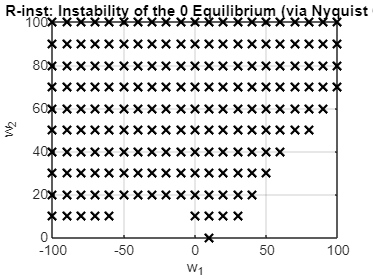


% Plot Rinst 
figure;
plot(w1_Rinst, w2_Rinst, 'kx', 'MarkerSize',8, 'LineWidth',1.5);
xlabel('w_1');
ylabel('w_2');
title('Region R-inst: Instability of the 0 Equilibrium (via Nyquist Criterion)');
grid on;

**1 (iv) Interconnection to a small robotic insect**

% Modelling of wings 
m=0.001;
cv=0.1;
cp=2;
A=[0 1;-cp/m -cv/m];
B=[0;1/m];
Bphi=[0;0];
Br=[0;1/m]

Br = 2×1
           0
        1000


C=[30 1];
Dr=0;

% checking excess of output passivity
lambda = 20

lambda = 20

epsilon=10^-8

epsilon = 1.0000e-08

bet=0

bet = 0

alph=-0.06

alph = -0.0600


cvx_begin sdp
cvx_solver SDPT3
cvx_precision high
n = length(A);
variable Y(n,n) symmetric
variable Z(1,n) 
 
 LMI1 = [[Y*A' + A*Y + 2*lambda*Y + Z'*Bphi'+ Bphi*Z + epsilon*eye(n) , Br-Y*C', Y*C']; 
 [ Br'-C*Y' , -(Dr+Dr')-bet*eye(1) , Dr'];
 [ C*Y , Dr , (1/alph)*eye(1)]] <= 0;



 LMI2 = [[Y*A' + A*Y + 2*lambda*Y + Z'*Bphi'+ Bphi*Z + epsilon*eye(n) , Br-Y*C', Y*C']; 
 [ Br'-C*Y' , -(Dr+Dr')-bet*eye(1) , Dr'];
 [ C*Y , Dr , (1/alph)*eye(1)]] <= 0;

cvx_end

 
Calling SDPT3 4.0: 20 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  8,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.0e+04|5.7e+00|3.2e+05| 3.333333e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.957|0.958|3.4e+03|2.4e-01|8.8e+03|-5.239902e+03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.634|0.636|1.3e+03|8.7e-02|2.9e+03|-5.544794e+03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.302|0.486|8.8e+02|4.5e-02|2.1e+03|-6.547348e+03  0.000000e+



% Design of w to enforce 2 passivity with shortage from r to - y

C2=[0 0 -1];
A = [-10 0 10;0 -100 100;0 0 -1];
B = [0; 0 ; 1];
Bphi = [0; 0 ; 1];
Br = [0 ; 0 ; 1];
Dr=0;

lambda = 20

lambda = 20

epsilon=10^-6

epsilon = 1.0000e-06

bet=0.05

bet = 0.0500



cvx_begin sdp
cvx_solver SDPT3
cvx_precision high
n = length(A);
variable Y(n,n) symmetric
variable Z(1,n) 

 
 LMI1 = [[Y*A' + A*Y + 2*lambda*Y + Z'*Bphi'+ Bphi*Z + epsilon*eye(n) , Br-Y*C2']; 
 [ Br'-C2*Y' , -(Dr+Dr')-bet*eye(1)]]<= 0;

 LMI2 = [[Y*A' + A*Y + 2*lambda*Y + epsilon*eye(n) , Br-Y*C2']; 
 [ Br'-C2*Y' , -(Dr+Dr')-bet*eye(1)]]<= 0;

 LMI3 = Y*A'+A*Y+Z'*Bphi'+Bphi*Z+epsilon*eye(n)<= 0;

cvx_end

 
Calling SDPT3 4.0: 26 variables, 9 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  9
 dim. of sdp    var  = 11,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.0e+02|2.4e+00|1.0e+04|-1.900003e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.710|0.940|2.6e+02|1.4e-01|2.1e+03|-4.764167e+00  0.000000e+00| 0:0:00| chol  1  1 
 2|0.872|0.946|3.3e+01|7.9e-03|2.5e+02|-1.305996e+00  0.000000e+00| 0:0:00| chol  1  1 
 3|0.608|0.888|1.3e+01|9.1e-04|1.2e+02|-5.801950e+00  0.000000e+


% state feedback controller

K =Z*inv(Y)

K = 1×3
 -127.3015   49.9121   30.8485


**1 (iv)**

T=10;
samples=1000;

% rho = 5
rho=5;
q=0;
SIM10 = sim('coursework2model2', linspace(0,T,samples))

SIM10 =   Simulink.SimulationOutput:

                  state: [1x1 timeseries] 
                   tout: [1000x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


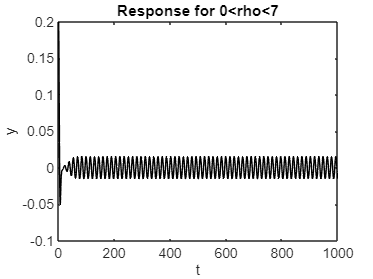

figure
plot(SIM10.state.data(:,1),'k','linewidth',1)
ylabel('y')
xlabel('t')
title('Response for 0<rho<7')


% rho = 9
rho=9;
SIM11 = sim('coursework2model2', linspace(0,T,samples))

SIM11 =   Simulink.SimulationOutput:

                  state: [1x1 timeseries] 
                   tout: [1000x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


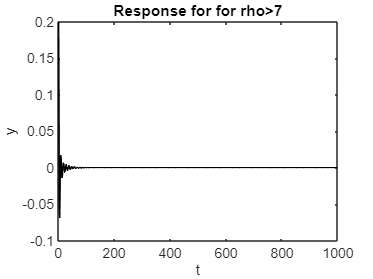

figure
plot(SIM11.state.data(:,1),'k','linewidth',1)
ylabel('y')
xlabel('t')
title('Response for for rho>7')

**2. Pharmacokinetics**

s=tf('s');
G1=(s+0.06)/(s^2+0.17*s+0.0016)


G1 =
 
        s + 0.06
  ---------------------
  s^2 + 0.17 s + 0.0016
 
Continuous-time transfer function.
Model Properties


G2= exp(-0.1*s)/(10*s+1)


G2 =
 
                   1
  exp(-0.1*s) * --------
                10 s + 1
 
Continuous-time transfer function.
Model Properties


G=G1*G2


G =
 
                             s + 0.06
  exp(-0.1*s) * -----------------------------------
                10 s^3 + 2.7 s^2 + 0.186 s + 0.0016
 
Continuous-time transfer function.
Model Properties


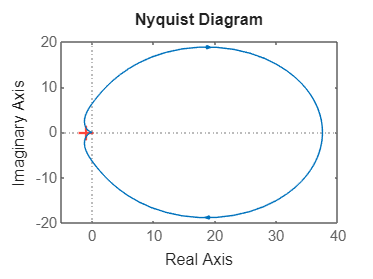

figure
nyquist(G) 